# Delayed Feedback System for Franka Emika Panda

Add Path

clear;clc;
addpath("PandaDyn\")
addpath("Dynamics\")
addpath("utils\")
addpath("..\ReadYAML\")
config=ReadYaml("Configuration\FrankaEmikaPanda.yaml");

The system follows


$$M\left(\vec{q} (t)\right) \ddot{\vec{q}} (t) + G \left( \vec{q} (t) \right) = - K_{p} \left( \vec{q} \left( t - \frac{3}{2} t_{s} \right) - \vec{q}_{d} \right) - K_{d} \dot{\vec{q}} \left( t - \frac{3}{2} t_{s} \right) - f \left( \dot{\vec{q}} \right),$$


where friction follows


$$f^{j} (\dot{q})= \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \left( \dot{q}_{j} + \varphi_{3,j} \right)}} - \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \varphi_{3,j}}}.$$


## Configurations

Dimension

dimension=7;

Precision and truncation rank

precision=30;
trunc_rank=-1;

Target Position

target=config.TargetAngle';

Gains

K_p=diag(config.Kp);
K_d=diag(config.Kd);

## Define symbolic variables and matrixes

Define elements

syms omega tau c s % c for \cos(\omega \tau), s for \sin(\omega \tau)
syms re_id im_id

Get matrixes

M_d=get_MassMatrix(target);
K_f=get_LinearizedFrictionMatrix();
q = sym('q_%d',[dimension 1]);
K_G=subs(jacobian( ...
    get_GravityVector(q),q),q, ...
    target);
clear q
K_G=double(K_G);

## Coeffient matrix

Delay time

% tau=1.5e-3;

Coeffient matrix

coeff_mat=-M_d*omega^2*re_id+tau^2*K_G*re_id+im_id*tau*K_f*omega+...
    c*(tau^2*(K_p-K_G)*re_id+im_id*tau*K_d*omega)+...
    s*(tau*K_d*omega*re_id-im_id*tau^2*(K_p-K_G));
tic
det_result= det(coeff_mat);
toc

历时 0.856433 秒。


det value

[real_part,imag_part]=complex_seperate(det_result,re_id,im_id,dimension);

Seperate real and imag parts

syms theta
% real_part=simplify(subs(real_part,[c,s],[cos(theta),sin(theta)]));
% imag_part=simplify(subs(imag_part,[c,s],[cos(theta),sin(theta)]));
real_part=simplify(subs(real_part,[c,s],[cos(omega),sin(omega)]));
imag_part=simplify(subs(imag_part,[c,s],[cos(omega),sin(omega)]));
real_part=combine(real_part,"sincos");
imag_part=combine(imag_part,"sincos");
vpa(subs(real_part,tau,2e-2),6)

vpa(subs(imag_part,tau,2e-2),6)

curve_real=@(tau_,x)subs(real_part,[omega,tau],[x,tau_]);
curve_imag=@(tau_,x)subs(imag_part,[omega,tau],[x,tau_]);
tau_test=0:1e-5:2e-3;
x_test=0:1e-3:1;
[X,Tau]=meshgrid(x_test,tau_test);
Val_real=zeros(size(X));
Val_imag=zeros(size(X));
tic
% for i=1:height(X)
%     parfor j=1:width(X)
%        Val_real(i,j)=curve_real(Tau(i,j),X(i,j));
%        Val_imag(i,j)=curve_imag(Tau(i,j),X(i,j));
%     end
% end

linear_real = Val_real(:);
linear_imag = Val_imag(:);
parfor k=1:height(X)*width(X)
    [i,j]=ind2sub([height(X),width(X)],k);
    linear_real(k)=curve_real(tau_test(i),x_test(j));
    linear_imag(k)=curve_imag(tau_test(i),x_test(j));
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


Val_real = reshape(linear_real, height(X),width(X));
Val_imag = reshape(linear_imag, height(X),width(X));
toc

历时 519.084629 秒。


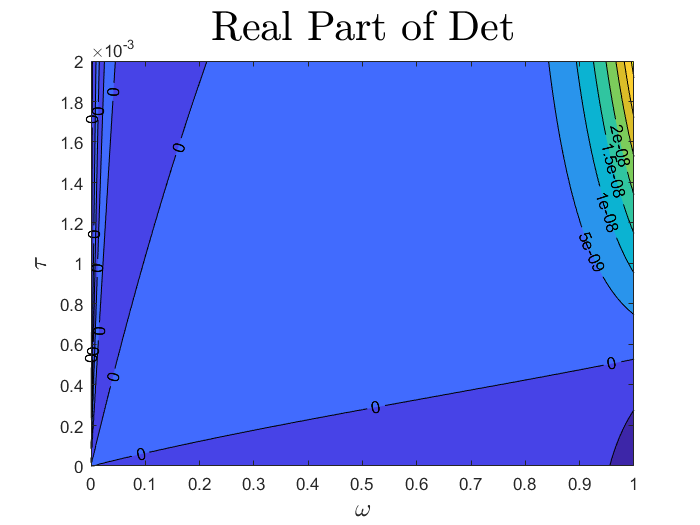

contourf(X,Tau,Val_real,'ShowText','on')
xlabel("$\omega$","FontSize",15,"Interpreter","latex")
ylabel("$\tau$","FontSize",15,"Interpreter","latex")
title("Real Part of Det","FontSize",25,"Interpreter","latex")

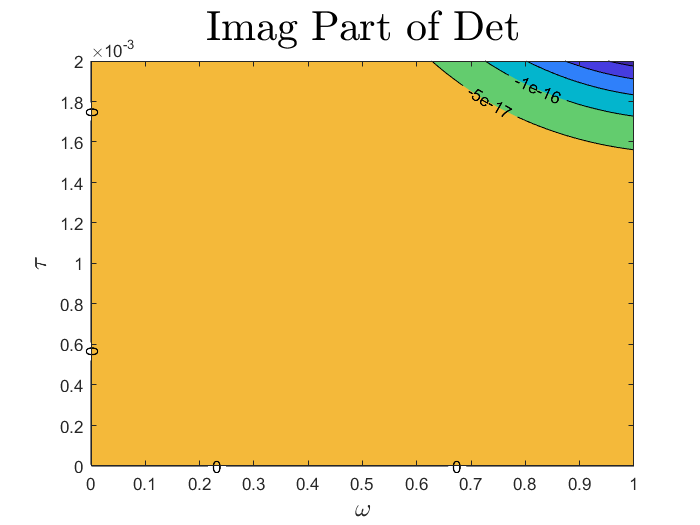

contourf(X,Tau,Val_imag,'ShowText','on')
xlabel("$\omega$","FontSize",15,"Interpreter","latex")
ylabel("$\tau$","FontSize",15,"Interpreter","latex")
title("Imag Part of Det","FontSize",25,"Interpreter","latex")